**Translación en la Frecuencia**

%%Aplicando las propiedades 
clear all;
close all;
clc;
% Espectro de magnitud Original
Fs = 210;       %Frecuencia de muestreo
t = -1:1/Fs:2;  %Vector de tiempo
L = 3000;       %Longitud de la señal 
A = 3;          %Escalar
X = A*((4/3)*t-2/3);%Señal multiplicada por escalar
Y= fft(X,L)   %Transformada rápida

Y = 	1.0e+03 *

   0.0000 + 0.0000i  -0.4899 - 0.6316i  -1.3525 - 0.3473i  -1.5139 + 0.6551i  -0.7321 + 1.3316i   0.1684 + 1.0633i   0.3451 + 0.3241i  -0.1049 - 0.0099i  -0.4250 + 0.2697i  -0.2159 + 0.5996i   0.1595 + 0.4909i   0.1889 + 0.1284i  -0.0960 + 0.0060i  -0.2509 + 0.2212i  -0.0771 + 0.4041i   0.1453 + 0.2852i   0.1053 + 0.0495i  -0.1061 + 0.0237i  -0.1696 + 0.2051i  -0.0095 + 0.3022i   0.1266 + 0.1743i   0.0494 + 0.0143i  -0.1098 + 0.0435i  -0.1149 + 0.1943i   0.0293 + 0.2323i   0.1046 + 0.1046i   0.0088 + 0.0011i  -0.1062 + 0.0628i  -0.0723 + 0.1827i   0.0516 + 0.1778i   0.0805 + 0.0585i  -0.0208 + 0.0007i  -0.0965 + 0.0798i  -0.0376 + 0.1683i   0.0624 + 0.1327i   0.0558 + 0.0284i  -0.0415 + 0.0079i  -0.0822 + 0.0932i  -0.0095 + 0.1509i   0.0646 + 0.0950i   0.0317 + 0.0103i  -0.0544 + 0.0196i  -0.0648 + 0.1021i   0.0124 + 0.1310i   0.0600 + 0.0639i   0.0096 + 0.0015i  -0.0603 + 0.0332i  -0.0460 + 0.1062i   0.0281 + 0.1095i   0.0506 + 0.0392i


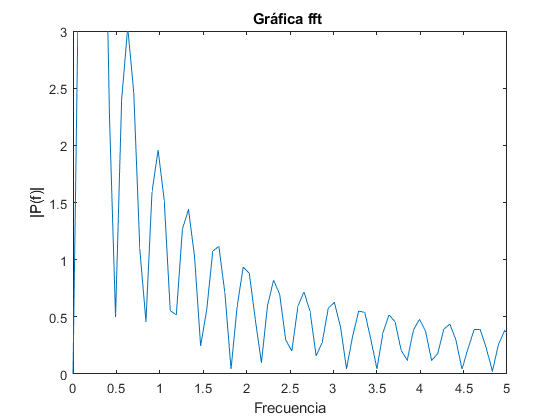


P = abs(Y/Fs);
f = linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica fft ')
xlabel('Frecuencia')
ylabel('|P(f)|')

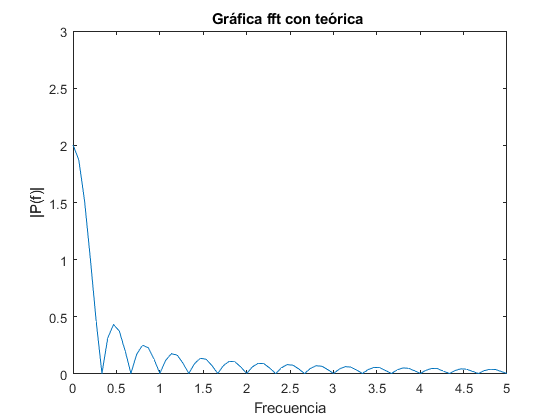


%Traslación en frecuencia
Fs = 200;       %Frecuencia de muestreo
t = -1:1/Fs:2;  %Vector de tiempo
L = 3000;       %Longitud de la señal 
A = 500;          %Escalar
Tras_f =((4/3)*(exp(1i*t*A))-2/3);%S
Y= fft(Tras_f,L);    %Transformada rápida

P = abs(Y/Fs);
f = linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica fft con teórica ')
xlabel('Frecuencia')
ylabel('|P(f)|')

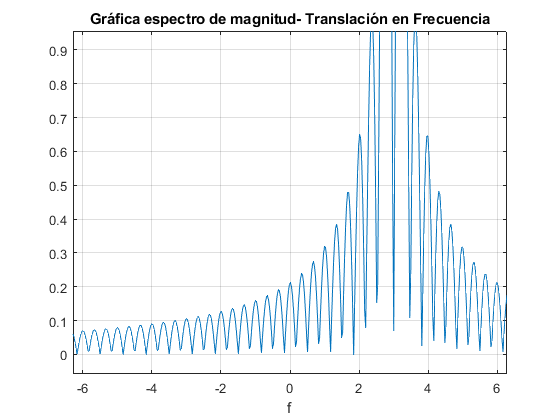



syms t f;       %Variables simbólicas
e=3;
x=exp(2*pi*1i*t*e)*((4/3)*t-2/3);  %
%x=(((4/3)*exp(1i*t*e))-2/3);  %
Tras_f=int(x*exp(-1i*2*pi*f*t),t,-1,2); %Transformada de Fourier teórica
%hold on         %sobreposición
% fplot(f,abs(Tras_f))
% title('Variación de la Frecuencia')
% figure

%-----Gráfica espectro de magnitud
ezplot(abs(Tras_f));
title('Gráfica espectro de magnitud- Translación en Frecuencia')
grid on

Espectro